
clc
close
clear

loadIn = load('C:\Users\v.krueger\MATLAB Drive\John Studies Drive\data\exampleData.mat');
loadContactLT = load('C:\Users\v.krueger\MATLAB Drive\John Studies Drive\data\exampleContact.mat');

% data = loadIn.
data = loadIn.tempRaw_Signal;
contactLT = loadContactLT.tempRawContact_Signal;
contactLT = contactLT/1000;
stepData = data;

[ind , x] = find(contactLT==0);
[ind2, x2] = find(contactLT);
contactData = contactLT;


stepData2 = data;
stepData2(ind2) = NaN; %Data where toeOff (ipsilateral)
stepData(ind) = NaN;  %Data where HeelStrike (ipsilateral)

%counter to iterate through the Gait Cycle
stepCounter = 1;
%state of the Gait Cycle
initial_FootContact = 1; 
toeOff_FootContact = 2;
nextInitial_FootContact =3;
%count the number of completed Gait Cycles
cycleCounter =0;
%Vector to save indices
fillerVector = zeros(3,1);

%Matrix for each foot Contact;
fillerMatrix = [];

% stepData(contactLT==0) = newContact
for i = 1:length(stepData)-1

    %we enter a phase change of contact here from either 0  to  1 or from
    %1 to 0, as given by the contactData
    if (contactData(i) + contactData(i+1)) == 1
        disp(i);
        switch stepCounter
            %we encounter a problem for every step but the first
            %it is important to ensure, that the last Index (where
            %stepCounter = 3) is the same as the next (stepCounter = 1)
            %incremented by 1;

            %Solution: 
            %Case: nextInitial_FootContact
            %saves both the
            %initial+Nextinitial-/footContact into the Vector/matrix 
            case initial_FootContact
                fprintf("Stepcounter is %s", string(stepCounter));                
                stepCounter = stepCounter+1;
                fillerVector(1) = i+1;
                continue;
            case toeOff_FootContact
                fprintf("Stepcounter is %s", string(stepCounter));
                stepCounter = stepCounter+1;
                fillerVector(2) = i;
                continue;
            case nextInitial_FootContact
                fprintf("Stepcounter is %s", string(stepCounter));   
                stepCounter = 1;
                cycleCounter = cycleCounter+1;
                fillerVector(3) = i;
                fillerMatrix(cycleCounter,:) = fillerVector;
                fillerVector(1) = i+1;
                continue;
        end
    end
end

     7



Stepcounter is 1

    55



Stepcounter is 2

   102



Stepcounter is 3

   164



Stepcounter is 1

   210



Stepcounter is 2

   272



Stepcounter is 3

   319



Stepcounter is 1

   381



Stepcounter is 2

   429



Stepcounter is 3

   489



Stepcounter is 1

   538



Stepcounter is 2

   598



Stepcounter is 3

   645



Stepcounter is 1

   707



Stepcounter is 2

   754



Stepcounter is 3

   815



Stepcounter is 1

   861



Stepcounter is 2

   923



Stepcounter is 3

   972



Stepcounter is 1

        1034



Stepcounter is 2

        1083



Stepcounter is 3

        1142



Stepcounter is 1

        1193



Stepcounter is 2

        1254



Stepcounter is 3

## Normalize here

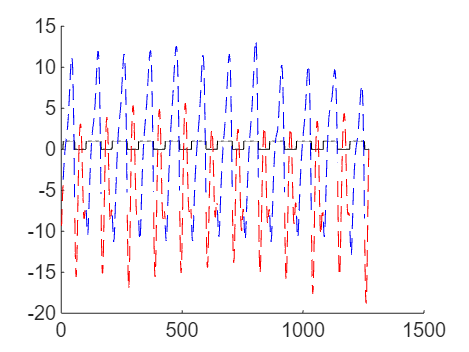

figure;
% plot(data,'r--');
hold on;
plot(contactLT,'k');
plot(stepData2,'r--');
plot(stepData,'b--');

hold off;